# Particle Double Pendulum

## Problem Statement

The first of the two parts of this problem is described in the Canvas assignment below. We will set up the equations of motion and then solve them numerically. The results will be summarized in an x-y plot of the angular displacements. An animation will also be created to help describe the system behavior.

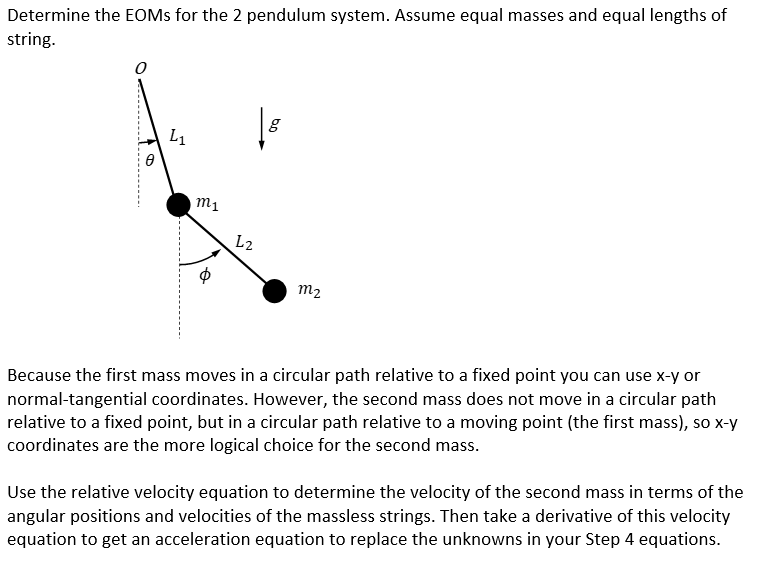

## Step 1: Conceptualize The Problem

Find the angular displacements as functions of time by determining the EOMs and numerically integrating them using ode45. The variables used for the angles will be $\theta$ and $\phi$ rather than $\theta_1$ and $\theta_2$, respectively, shown in the sketch above.

- 2 degrees of freedom

- Gravity is acting

- Masses move without any friction or drag

- Assume particle dynamics - point masses, massless rods

- Equal masses, equal lengths

- Assume initial conditions can be specified (want to study various IC's)

## Step 2: Coordinate System

A normal-tangential coordinate system is used from the origin to mass 1. A Cartesian system is used for mass 2. Constraint equations will be used to relate the Cartesian components to the angles.

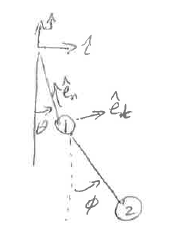

## Step 3: Free-Body Diagram

Individual FBDs for mass 1 and 2.

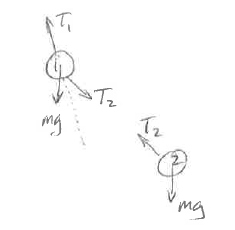

## Step 4: Fundamental Equations

The EOMs are derived starting with Newton's second law


$$\bar{F}=m\bar{a}$$


Details are in the appendix, but the resulting equations are


$$mL\dot{\theta}^2=-mg\cos{\theta}+T_1-T_2\cos{(\phi-\theta)}$$



$$mL\ddot{\theta}=-mg\sin{\theta}+T_2\sin{(\phi-\theta)}$$



$$m\ddot{x}_2=-T_2\sin{\phi}$$



$$m\ddot{y}_2=-mg+T_2\cos{\phi}$$


syms m g L theta theta_dot theta_ddot phi phi_dot phi_ddot x_ddot y_ddot T1 T2

eqn(1) = m*L*theta_dot^2 == -m*g*cos(theta)+T1-T2*cos(phi-theta);
eqn(2) = m*L*theta_ddot == -m*g*sin(theta)+T2*sin(phi-theta);
eqn(3) = m*x_ddot == -T2*sin(phi);
eqn(4) = m*y_ddot == -m*g+T2*cos(phi);

## Step 5: Knowns and Unknowns

### Knowns


$$m, g, L, \theta_0, \dot{\theta}_0, \phi_0, \dot{\phi}_0$$


### Unknowns

$\theta$: angular position of mass 1 (measured from downward vertical)

$\phi$: angular position of mass 2 (measured from downward vertical)

$T_1$: force in pendulum rod 1

$T_2$: force in pendulum rod 2

$x$: horizontal displacement of mass 2

$y$: vertical displacement of mass 2

## Step 6: Constraints

Constraints between acceleration components.


$$\ddot{x}_2=L\ddot{\theta}\cos{\theta}-L\dot{\theta}^2\sin{\theta}+L\ddot{\phi}\cos{\phi}-L\dot{\phi}^2\sin{\phi}$$



$$\ddot{y}_2=L\ddot{\theta}\sin{\theta}+L\dot{\theta}^2\cos{\theta}+L\ddot{\phi}\sin{\phi}+L\dot{\phi}^2\cos{\phi}$$


eqn(5:6) = [x_ddot,y_ddot] == L*theta_ddot*[cos(theta),sin(theta)]+...
    L*theta_dot^2*[-sin(theta),cos(theta)]+L*phi_ddot*[cos(phi),sin(phi)]+...
    L*phi_dot^2*[-sin(phi),cos(phi)];

Now have 6 eqs and 6 unknowns.

## Step 7: Obtain the EOMs

### Nonlinear EOMs

unknowns = solve(eqn,[theta_ddot,phi_ddot,T1,T2,x_ddot,y_ddot]);
theta_ddot = simplify(unknowns.theta_ddot)

$$theta\_ddot = -\frac{2\,L\,\sin\left(\varphi -\theta \right)\,{\dot{\varphi }}^{2}+L\,\sin\left(2\,\varphi -2\,\theta \right)\,{\dot{\theta }}^{2}+g\,\sin\left(2\,\varphi -\theta \right)-3\,g\,\sin\left(\theta \right)}{L\,\left(\cos\left(2\,\varphi -2\,\theta \right)-3\right)}$$

phi_ddot = simplify(unknowns.phi_ddot)

$$phi\_ddot = \frac{L\,\sin\left(2\,\varphi -2\,\theta \right)\,{\dot{\varphi }}^{2}+4\,L\,\sin\left(\varphi -\theta \right)\,{\dot{\theta }}^{2}+2\,g\,\sin\left(\varphi \right)+2\,g\,\sin\left(\varphi -2\,\theta \right)}{L\,\left(\cos\left(2\,\varphi -2\,\theta \right)-3\right)}$$

## Step 8: Solve the EOMs

### Solve nonlinear EOMs

Make all state variables symbolic functions of time

syms theta(t) theta_dot(t) phi(t) phi_dot(t)

Substitute these symbolic functions into the EOMs. Then have Matlab produce the eom sub-function using the odeFunction command. The 3 sets of arguments passed to odeFunction are the expressions for the derivatives of the state variables, the state variables, and then any other parameters that appear in the derivative expressions. Note that the order of the state variables and their derivatives is arbitrary but must be consistent.

accelEOMs = subs([theta_ddot;phi_ddot],...
    [str2sym('theta'),str2sym('phi'),str2sym('theta_dot'),str2sym('phi_dot')],...
    [theta,phi,theta_dot,phi_dot]);
eom = odeFunction([theta_dot;phi_dot;accelEOMs],[theta;phi;theta_dot;phi_dot],g,L);

Specify parameter values and integrate EOMs. Order of IC's must match state variables in odeFunction call.

gn = 9.81; % gravitational constant, m/s^2
Ln = 0.33; % length of each rod, m
IC(1) = pi/3; % initial theta
IC(2) = pi/18; % inital phi
IC(3) = 0; % initial theta-dot
IC(4) = 0; % initial phi-dot
t0 = 0; % initial time
tf = 10; % final time
ntime = 501; % number of time points
[T,S] = ode45(@(t,s)eom(t,s,gn,Ln),linspace(t0,tf,ntime),IC);

Plot time history of angles

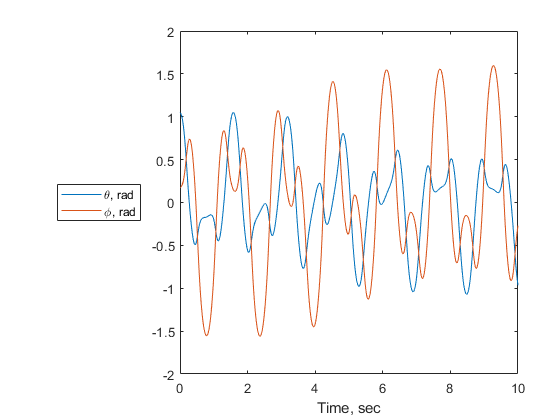

plot(T,S(:,1:2),'-')
xlabel('Time, sec')
legend('\theta, rad','\phi, rad','Location','WestOutside')

Add animation of motion:

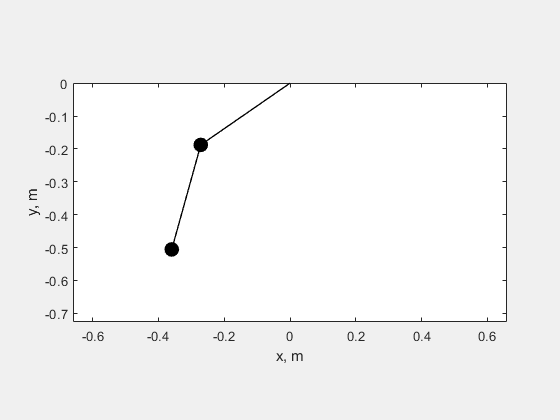

ax1 = Ln*sin(S(:,1));
ay1 = -Ln*cos(S(:,1));
ax2 = Ln*(sin(S(:,1))+sin(S(:,2)));
ay2 = -Ln*(cos(S(:,1))+cos(S(:,2)));
figure("Visible","on")
h = plot([0,ax1(1)],[0,ay1(1)],'-k',[ax1(1),ax2(1)],[ay1(1),ay2(1)],...
    '-ko','LineWidth',1,'MarkerSize',10,'MarkerFaceColor','k');
xlabel('x, m')
ylabel('y, m')
axis equal
ylim([-2*Ln*1.1,0])
xlim([-2*Ln,2*Ln])
for i = 2:length(ax1)
    set(h(1),'XData',[0,ax1(i)],'YData',[0,ay1(i)]);
    set(h(2),'XData',[ax1(i),ax2(i)],'YData',[ay1(i),ay2(i)]);
    drawnow
end

## Step 9: Does It Make Sense?

### Units

### Magnitudes

### Signs

## Appendix

### Contributions

who did what...

### Attachments

EOMs derived during class lecture.